# Arrow Geometry

Need to play around to identify the geometry of the arrow prior to caturing this in a function to be used in the conformal mapping of a flow pattern.

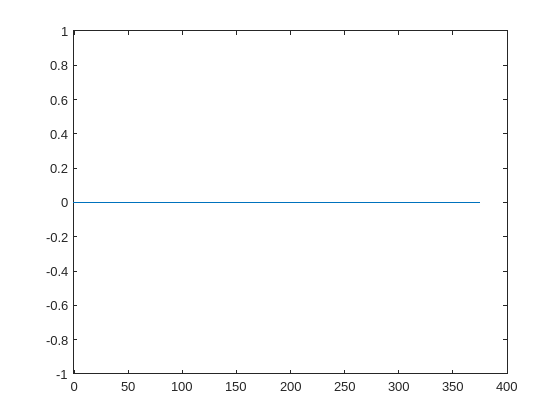

% Sets the geometrical parameters
Lt = 1.3;
Ln = 1.3;

Lm = 13.6;
Lc = 1.4;
D = 1;

Lf = 3; % total fin length



func_ellipse_y_pos = @(x,a,b) sqrt(b^2*(1-x.^2/a^2));
func_ellipse_y_neg = @(x,a,b) -sqrt(b^2*(1-x.^2/a^2));

pl_prof = @(x, f) plot(real(x), imag(x), f);

cap_resolution = 2000;

% Calculates the profiles for the leading cap
forw_cap_domain = linspace(-1, -1+Lc, cap_resolution);
forw_cap_top = func_ellipse_y_pos(forw_cap_domain+(1-Lc), Lc, D/2);
forw_cap_bottom = func_ellipse_y_neg(forw_cap_domain+(1-Lc), Lc, D/2);

top_forw_cap_z_pos = forw_cap_domain + j*forw_cap_top;
bottom_forw_cap_z_pos = forw_cap_domain + j*forw_cap_bottom;

figure
pl_prof(top_forw_cap_z_pos, '');


% Calculates the profiles for the main body
main_length_left = -1+Lc;

main_length_left = 1.4000

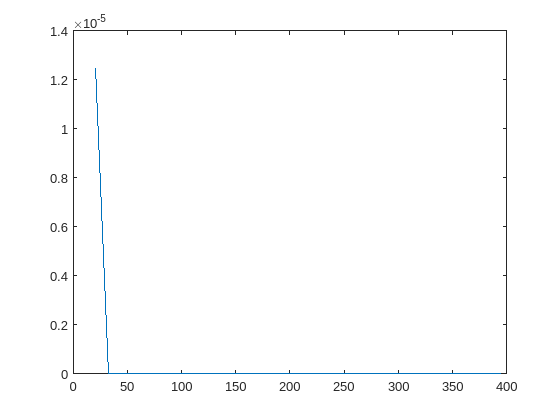

top_main_length_z_pos = linspace(main_length_left, main_length_left + Lm) + j*D/2;
bottom_main_length_z_pos = top_main_length_z_pos - j*D;

% Normally the fin would go here (currently will assume to be a flat
% profile for now
fin_start = main_length_left + Lm;

top_fin_profile_z_pos = linspace(fin_start, fin_start+Lf, 10) + 1j*(D/2);
bottom_fin_profile_z_pos = top_fin_profile_z_pos - 1j*D;

% Calculates the profiles for the trailing region between where the fin
% would end and the end profile as well
trail_start = fin_start + Lf;

top_trail_profile_z_pos = linspace(trail_start, trail_start+Ln, 10) + j*(D/2);
bottom_trail_profile_z_pos = top_trail_profile_z_pos - j*D;

% Calculates the profiles for the trailing cap
end_cap_start = trail_start + Ln;

end_cap_domain = linspace(end_cap_start, end_cap_start + Lt, cap_resolution);
end_cap_top = func_ellipse_y_pos(end_cap_domain-end_cap_start, Lt, D/2);
end_cap_bottom = func_ellipse_y_neg(end_cap_domain-end_cap_start, Lt, D/2);

top_end_cap_z_pos = end_cap_domain + j*end_cap_top;
bottom_end_cap_z_pos = end_cap_domain + j*end_cap_bottom;

figure
pl_prof(top_end_cap_z_pos, '');


% Plots the calculated profiles
figure
hold on
grid on
axis equal

pl_prof(top_forw_cap_z_pos, '');
pl_prof(top_main_length_z_pos, '');
pl_prof(top_fin_profile_z_pos, '');
pl_prof(top_trail_profile_z_pos, '');
pl_prof(top_end_cap_z_pos, '');

pl_prof(bottom_end_cap_z_pos, '');
pl_prof(bottom_trail_profile_z_pos, '');
pl_prof(bottom_fin_profile_z_pos, '');
pl_prof(bottom_main_length_z_pos, '');
pl_prof(bottom_forw_cap_z_pos, '');

arrow_profile_z_pos = create_fin_profile(...
    top_forw_cap_z_pos, ...
    top_main_length_z_pos, ...
    top_fin_profile_z_pos, ...
    top_trail_profile_z_pos, ...
    top_end_cap_z_pos)

arrow_profile_z_pos = 1.0e+02 *

  -0.0100 + 0.0000i   0.1086 + 0.0000i   0.1577 + 0.0000i   0.1954 + 0.0000i   0.2271 + 0.0000i   0.2551 + 0.0000i   0.2804 + 0.0000i   0.3036 + 0.0000i   0.3252 + 0.0000i   0.3455 + 0.0000i   0.3647 + 0.0000i   0.3829 + 0.0000i   0.4004 + 0.0000i   0.4171 + 0.0000i   0.4331 + 0.0000i   0.4486 + 0.0000i   0.4636 + 0.0000i   0.4781 + 0.0000i   0.4922 + 0.0000i   0.5059 + 0.0000i   0.5193 + 0.0000i   0.5323 + 0.0000i   0.5450 + 0.0000i   0.5574 + 0.0000i   0.5695 + 0.0000i   0.5814 + 0.0000i   0.5930 + 0.0000i   0.6044 + 0.0000i   0.6156 + 0.0000i   0.6266 + 0.0000i   0.6374 + 0.0000i   0.6481 + 0.0000i   0.6585 + 0.0000i   0.6688 + 0.0000i   0.6789 + 0.0000i   0.6889 + 0.0000i   0.6987 + 0.0000i   0.7084 + 0.0000i   0.7180 + 0.0000i   0.7274 + 0.0000i   0.7367 + 0.0000i   0.7459 + 0.0000i   0.7550 + 0.0000i   0.7639 + 0.0000i   0.7728 + 0.0000i   0.7815 + 0.0000i   0.7902 + 0.0000i   0.7987 + 0.0000i   0.8072 + 0.0000i   0.8155 + 0.0000i


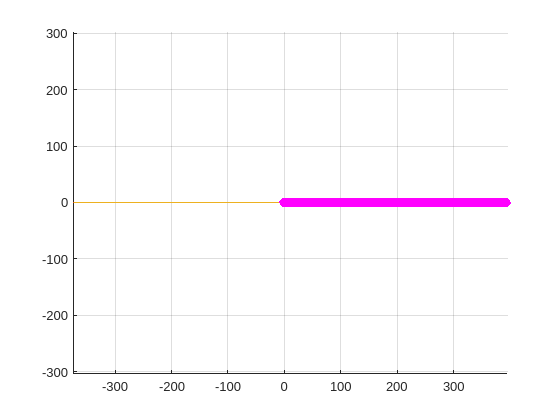


pl_prof(arrow_profile_z_pos, 'k--');

arrow_profile_interp_z_pos = interp_even_dists_from_z_profile(arrow_profile_z_pos, 2001);
pl_prof(arrow_profile_interp_z_pos, 'mo')


% figure
% tiledlayout(2, 1)
% nexttile
% plot(abs(arrow_profile_z_pos))
% nexttile
% plot(angle(arrow_profile_z_pos))

% plot(real(top_forw_cap_z_pos), imag(top_forw_cap_z_pos));
% plot(real(top_main_length_z_pos), imag(top_main_length_z_pos));
% plot(real(top_fin_profile_z_pos), imag(top_fin_profile_z_pos));
% plot(real(top_trail_profile_z_pos), imag(top_trail_profile_z_pos));
% plot(real(top_end_cap_z_pos), imag(top_end_cap_z_pos));
% 
% plot(real(bottom_cap_z_pos), imag(bottom_cap_z_pos))
% plot(real(bottom_main_length_z_pos), imag(bottom_main_length_z_pos));
% plot(real(bottom_forw_cap_z_pos), imag(bottom_forw_cap_z_pos));

Now that the interpolating function has been built to not mess up the conformal transformation, the fins need to be added instead of just a simple linear profile. Based on the functions as long as they have the same endpoints as the trailing and main body lines, the fins will fit directly into the model.

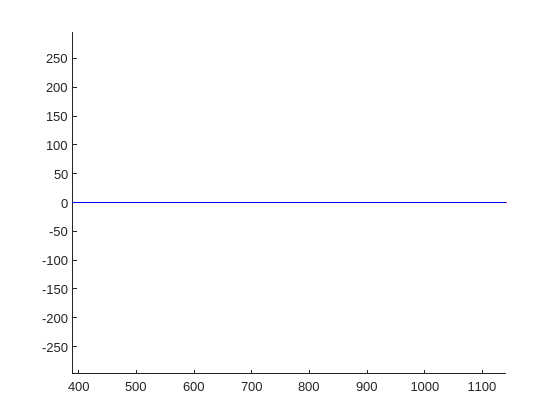

Lfl = 2.7; % length of leading fin
hf = 1; % height of fin

% Calculates the profile for the trailing edge of the fin
fin_trail_curve_start = fin_start + Lfl;

fin_trail_curve_domain = linspace(fin_trail_curve_start, fin_trail_curve_start + (Lf-Lfl), cap_resolution);
fin_trail_curve_top = func_ellipse_y_pos(fin_trail_curve_domain-fin_trail_curve_start, (Lf-Lfl), hf) + D/2;
% fin_trail_curve_bottom = func_ellipse_y_neg(fin_trail_curve_domain-fin_trail_curve_start, (Lf-Lfl), hf);

top_fin_trail_curve_z_pos = fin_trail_curve_domain + j*fin_trail_curve_top;

% Calculates the preceding linear profile
fin_preceding_domain = linspace(fin_start, fin_start + Lfl, cap_resolution);
top_fin_preceding = hf/Lfl * (fin_preceding_domain - fin_start) + D/2;

top_fin_preceding_curve_z_pos = fin_preceding_domain + j*top_fin_preceding;

figure
hold on
axis equal
pl_prof(top_fin_trail_curve_z_pos, '--r')
pl_prof(top_fin_preceding_curve_z_pos, 'b')


top_fin_linear_profile_z_pos = [top_fin_preceding_curve_z_pos top_fin_trail_curve_z_pos(2:end)];

Plot the entire arrow with the fin included as well. Once this profile is passed through the linear interpolation it should be good to pass through linear interpolation to make sure the Fourier transformation is balanced across the disk annual under transformation.

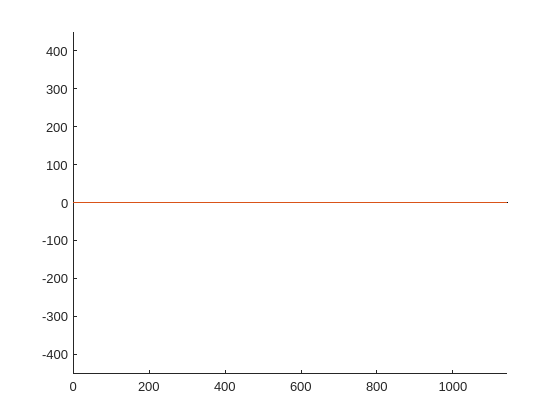

figure
hold on
axis equal

arrow_profile_w_fin_z_pos = create_fin_profile(...
    top_forw_cap_z_pos, ...
    top_main_length_z_pos, ...
    top_fin_linear_profile_z_pos, ...
    top_trail_profile_z_pos, ...
    top_end_cap_z_pos);

pl_prof(arrow_profile_w_fin_z_pos, 'k');

arrow_profile_interp_w_fin_z_pos = interp_even_dists_from_z_profile(arrow_profile_w_fin_z_pos, 2001);
pl_prof(arrow_profile_interp_w_fin_z_pos, '--')

function [arrow_profile_z_pos] = create_fin_profile(top_forw_cap, top_main_length, top_fin_profile, top_trail, top_end_cap)
    arrow_top_profile_z_pos = [ ...
        top_forw_cap ...
        top_main_length(2:end) ...
        top_fin_profile(2:end) ...
        top_trail(2:end) ...
        top_end_cap(2:end)
    ];
    % To not overlap the final point, when adding the reverse array
    % (additionally flipped across the origin), the end point (at the
    % halfway point of the full profile) has been removed
    arrow_bottom_profile_z_pos = conj(arrow_top_profile_z_pos(end:-1:1));

    % Note that the last point in the profile has not been removed given
    % that this value matches the starting value and is required for
    % proper interpolation.
    arrow_profile_z_pos = [arrow_top_profile_z_pos arrow_bottom_profile_z_pos(2:(end))];
end

function [interp_z_pos] = interp_even_dists_from_z_profile(z_profile, num_interp_points)
    num_profile_points = length(z_profile);
    dists_at_points = zeros(1, num_profile_points);

    % Computes the distance from the start of every point in the profile
    dists_at_points(1) = 0; % Starts at 0 distnace at the first point
    for i=2:num_profile_points
        dists_at_points(i) = dists_at_points(i-1) + abs(z_profile(i) - z_profile(i-1));
    end
    max_dist = dists_at_points(end);

    

    % Finds the distances that interpolation needs to be completed at
    incr_interp_dist = max_dist / (num_interp_points - 1);
    interp_dists = incr_interp_dist * (0:num_interp_points);
    
    % For each point to interpolate, finds the points with bounding
    % distance and then linearly interpolates the point

    interp_z_pos = zeros(1, num_interp_points);
    interp_z_pos(1) = z_profile(1); % Sets as are bounds of the interpolation
    interp_z_pos(end) = z_profile(end);

    for i=2:(num_interp_points-1)
        curr_dist = interp_dists(i);
        for j=1:num_profile_points
            if curr_dist >= dists_at_points(j) && curr_dist <= dists_at_points(j+1)
                % Interpolation must be made here
                lower_dist_z_pos = z_profile(j);
                lower_dist = dists_at_points(j);

                upper_dist_z_pos = z_profile(j+1);
                upper_dist = dists_at_points(j+1);

                interp_z_pos(i) = lower_dist_z_pos + (upper_dist_z_pos - lower_dist_z_pos) / (upper_dist - lower_dist) * (curr_dist - lower_dist);
                break
            end
        end
    end
end
